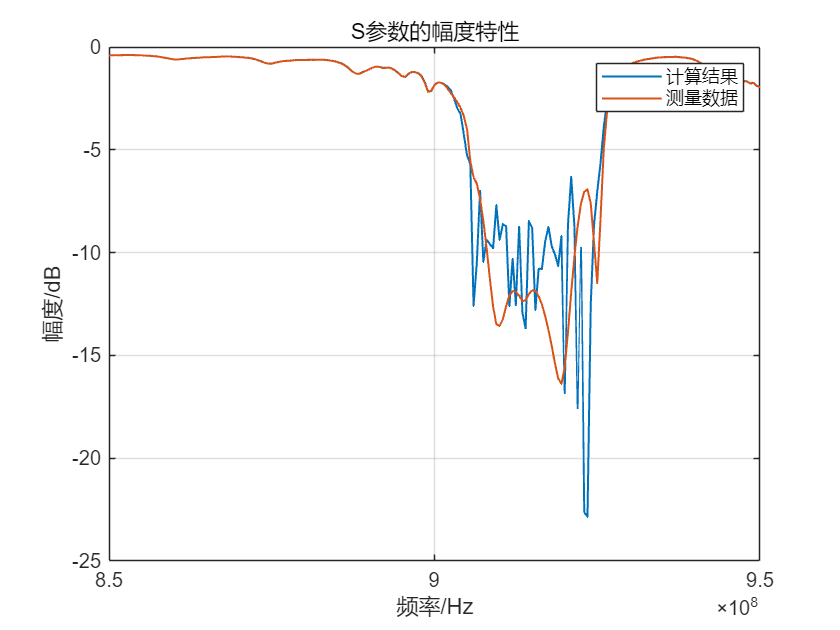

clear;
clc;
Z0=50;
filter=load('202512131.txt');      %1.双端口的S参数
isnonload=load('202512132.txt');   %2.不匹配负载（衰减器）的单端口S参数
loadtofilter=load('202512133.txt');%3.不匹配负载连接到待测滤波器的2端口，
                                   %   使用网络分析仪测量滤波器1端口的单端口S参数
freq1=isnonload(:,1);
freq2=filter(:,1);
freq3=loadtofilter(:,1);

gamma_l=10.^(isnonload(:,2)/20).*exp(1i*isnonload(:,3)); %Tl
S11=10.^(filter(:,2)/20).*exp(1i*filter(:,3));
S12=10.^(filter(:,6)/20).*exp(1i*filter(:,7));
S22=10.^(filter(:,8)/20).*exp(1i*filter(:,9));
gamma_in=S11+S12.*S12.*gamma_l./(1-S22.*gamma_l); %计算的Tin结果
S=10.^(loadtofilter(:,2)/20).*exp(1i*loadtofilter(:,3));         %测量的Tin结果
figure;
plot(freq1,20*log10(abs(gamma_in)),'LineWidth',1);
hold on;
plot(freq3,20*log10(abs(S)),'LineWidth',1);
xlabel('频率/Hz');
ylabel('幅度/dB');
title('S参数的幅度特性');
hold off
grid on;
legend('计算结果','测量数据');

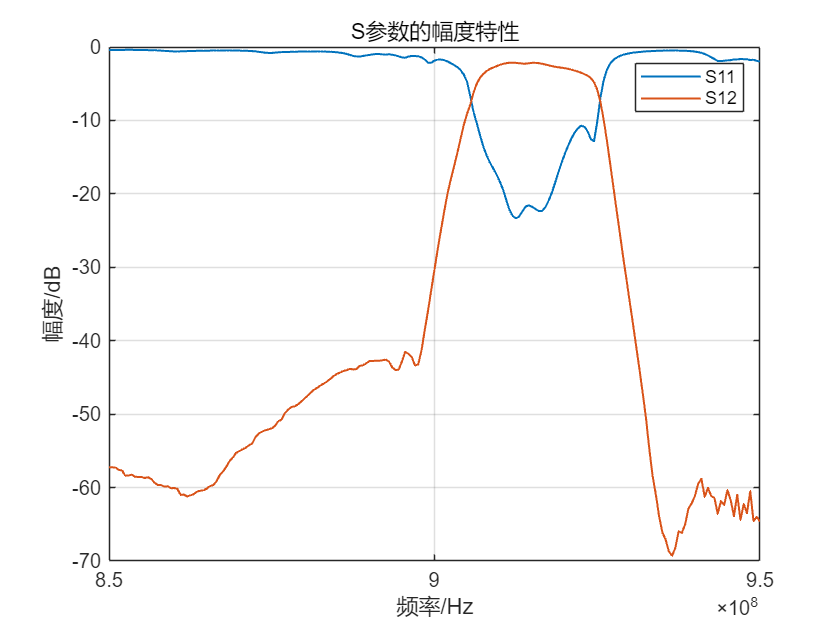


figure(2);
plot(freq1,20*log10(abs(S11)),'LineWidth',1);
hold on;
plot(freq3,20*log10(abs(S12)),'LineWidth',1);
xlabel('频率/Hz');
ylabel('幅度/dB');
title('S参数的幅度特性');
hold off
grid on;
legend('S11','S12');